# Nodal Analysis Lab

[⇦ DC Circuit Analysis Overview](matlab: OpenOverview)

In this lab, you will perform a nodal analysis of the linear circuit shown below in MATLAB. Afterward, you will build the circuit in Simscape and take voltage measurements to verify your result. Before completing this assignment, consider reviewing [NodalAnalysis.mlx](matlab: edit NodalAnalysis).

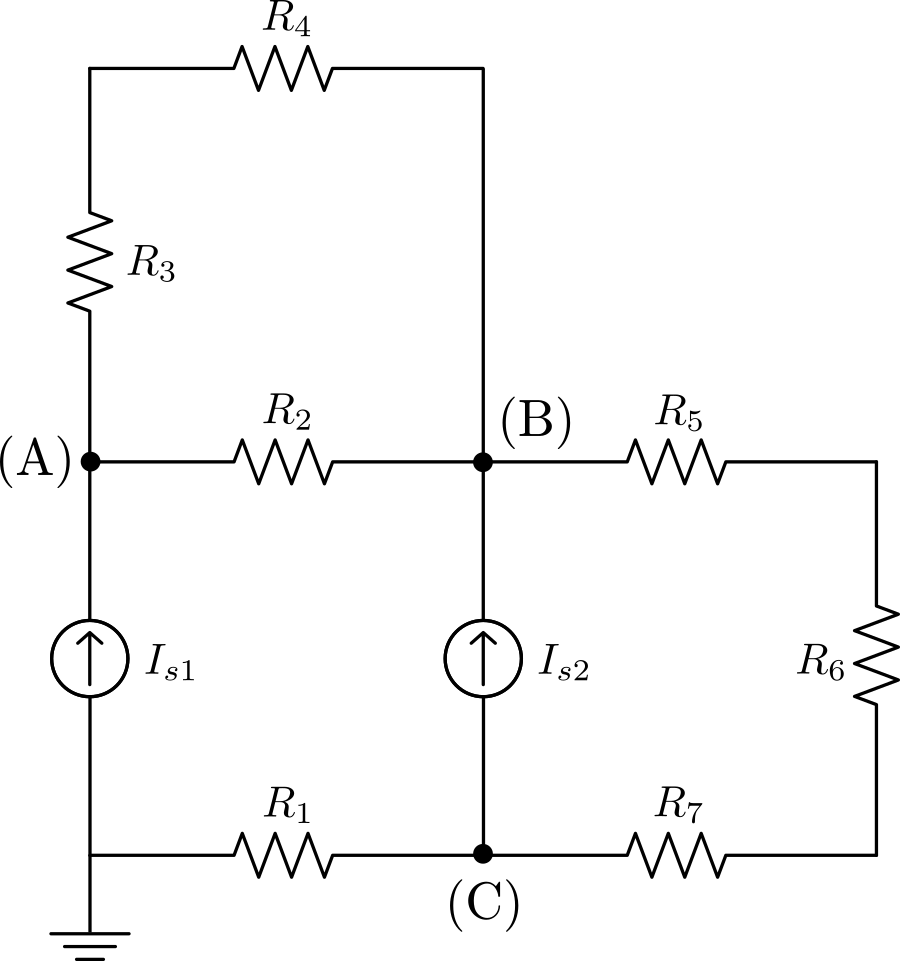

*Circuit to analyze*

The resistances and sources are

    
$$\begin{array}{l}
R_1 = 10 \ \Omega
\\
R_2 = 1  \ \text{k} \Omega
\\
R_3 = 500 \ \Omega
\\
R_4 = 500 \ \Omega
\\
R_5 = 20 \ \Omega
\\
R_6 = 220 \ \Omega
\\
R_7 = 10 \ \Omega
\end{array}$$
         
$$\begin{array}{l}
I_{s1} = 100 \ \text{mA}
\\
I_{s2} = 250 \ \text{mA}
\end{array}$$


Follow the steps below to compute the node voltages at (A), (B), and (C).

### **Part 1. Nodal analysis in MATLAB**

**Task 1.** Decide which nodes are required to analyze the circuit. Use the indicated ground as the reference node.

**Solution. **

The circuit can be simplified to

    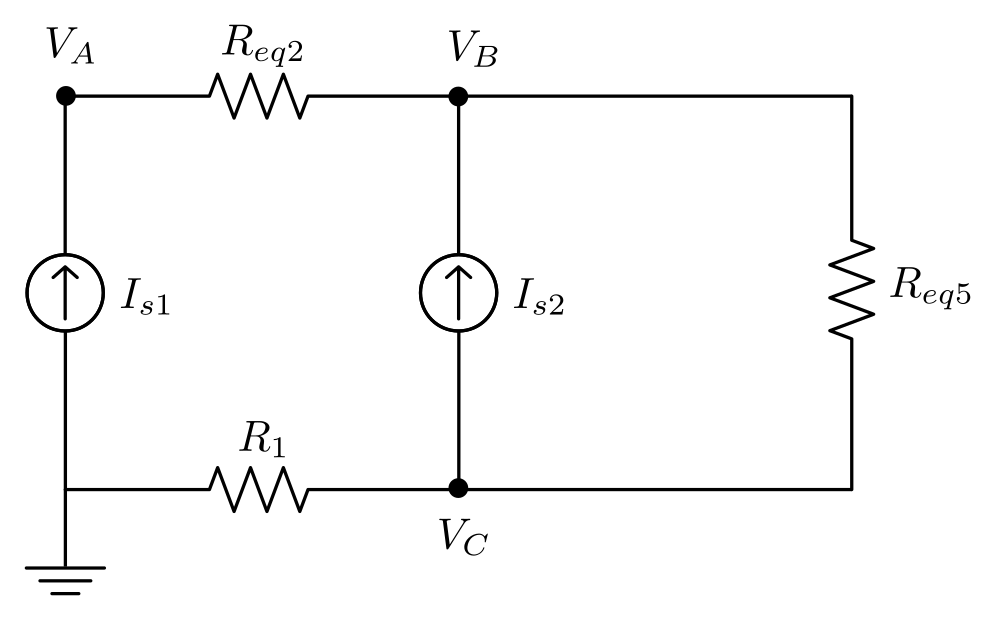

So only the node voltages $V_b$ and $V_c$ are essential to the analysis.

**Task 2. **Apply KCL to each node to generate the equations.

**Solution.**

**Node B.** $I_{s1}  + I_{s2} + \frac{V_C - V_B}{R_{eq5}} = 0$

**Node C. **$\frac{0 - V_C}{R_1} - I_{s2} + \frac{V_B - V_C}{R_{eq5}} = 0$

**Task 3. **Using the equations you derived in **Task 2**, create the matrix form of the equations. 

Setting

    
$$\mathbf{V} = \left[ \begin{array}{l} V_B \\ V_C \end{array} \right]$$
 

The matrix form is

    
$$\left( \begin{array}{ccc}  
-{R_{eq5}}^{-1} &  {R_{eq5}}^{-1}
\\
{R_{eq5}}^{-1} &  -{R_{1}}^{-1} -  {R_{eq5}}^{-1}
\end{array} \right)
\left( \begin{array}{l} V_B \\ V_C \end{array} \right)
=
\left( \begin{array}{c} 
- I_{s1} - I_{s2} \\
I_{s2} 
\end{array} 
\right)$$


**Task 4. **Using the space provided below, define the values of the resistors in ohms and the current sources in amps.

% Define the resistances and current sources
R1 = 10;
Req2 = 500;
Req5 = 250;
Is1 = 0.1;
Is2 = 0.25;

**Task 5. **With the resistances and voltages defined, you can define the matrix system in MATLAB. Define the coefficient matrix `M` and constant vector `b` in the space below. Then, solve the vector of node voltages.

% Write your code here
M = [-1/Req5, 1/Req5;
     1/Req5, -1/R1 - 1/Req5];
b = [-Is1-Is2;
       Is2    ];
V = M\b

**Task 6. **If you didn't already compute the voltages at all three points (A, B, and C), do so here.

% Write your code here
VB = V(1)
VC = V(2)
VA = VB + Is1*Req2

### **Part 2. Simscape model analysis**

In this section, you will check your result from **Part 1** by creating a model of the electrical circuit in Simscape and then measuring the currents.

**Task 7. **Open the model:

[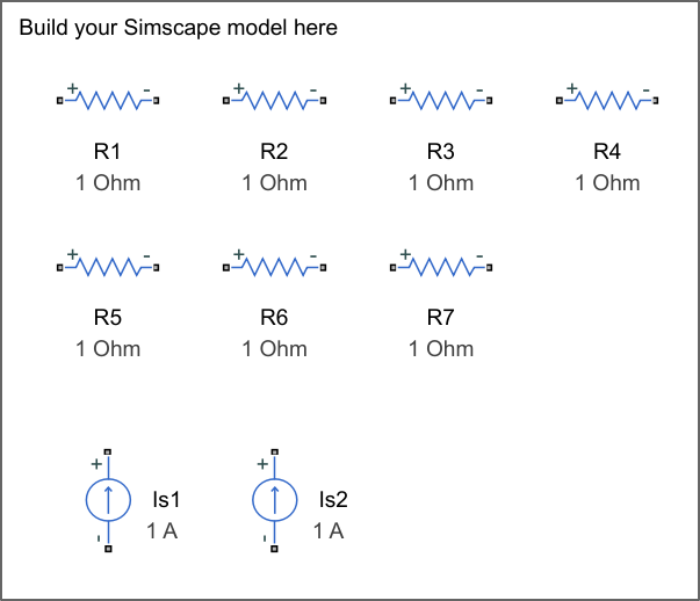](matlab: NodalAnalysisCircuit)

[`NodalAnalysisCircuit.slx`](matlab: NodalAnalysisCircuit)

**Task 8.** Complete the model by connecting the circuit elements to match the circuit diagram defined in the previous section.

**Task 9.** Use the multimeter to measure each of the node voltages. For detailed instructions on how to use the virtual multimeter to measure voltage, see the instructions in the last part of [NodalAnalysis.mlx](matlab: edit NodalAnalysis).

[⇦ DC Circuit Analysis Overview](matlab: OpenOverview)